# Pregunta 4

## Maximiliano Rivera

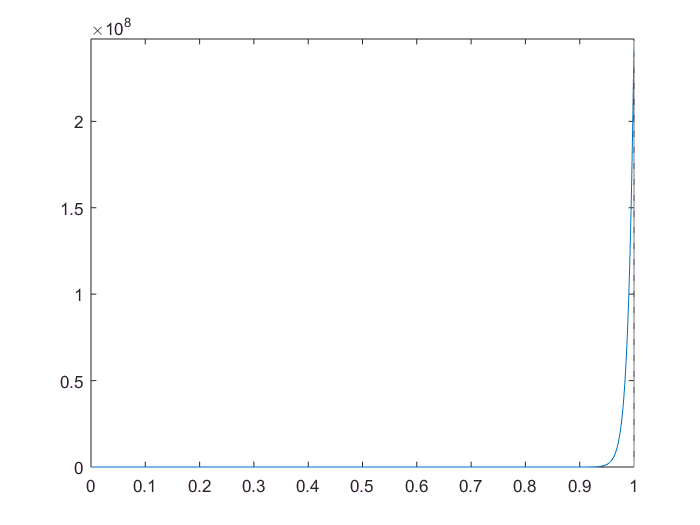

f = @(t) e.^(sin(4*t))/2006.787453080206;
fplot(f, [0, 1])

m = 100; % Puntos
t = linspace(0,1, m);
b = f(t)';
% n = 15;
% x = linspace(0, 1, n);

- Método utilizando Ecuaciones Normales

Se utiliza la matriz de Vandermonde en el sistema $Ax = b$, el cual hay que minimizar.

Con x de la forma $x = (a_0, a_1, \dots, a_{14})^T$, A es la matriz de Vandermonde.

A = fliplr(vander(t));
A = A(:, 1:15);
Aprima = A'*A;
bprima = A'*b;
[R] = chol(Aprima)

Error using chol
Matrix must be positive definite.

Como $A^*A$no es positiva definida, no presenta decomposición de Cholesky.

- Householder

A = vander(t);
[Q, R] = qr(A);
bprima = Q'*b;
coef = R\bprima;

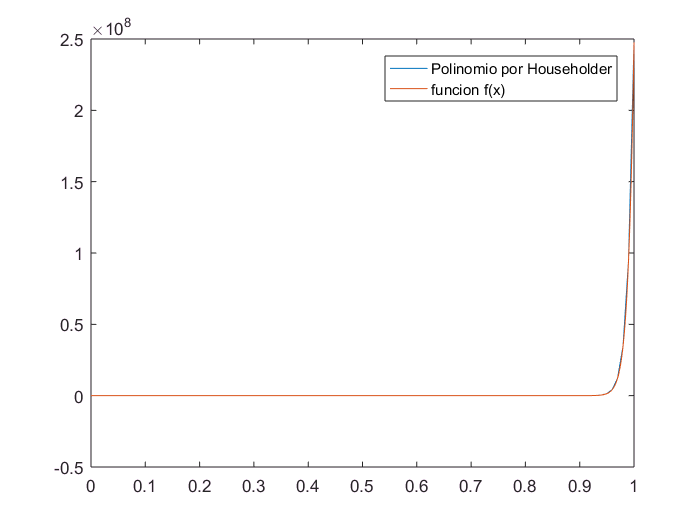

coef_15_Householder = coef(1);
pol = polyval(coef, t);
plot(t, pol)
hold on;
fplot(f, [0, 1])
legend('Polinomio por Householder', 'funcion f(x)');
hold off;

Podemos notar que el ajuste es preciso para $x < 0.9$aproximadamente, luego a esto, existe una diferencia considerable.

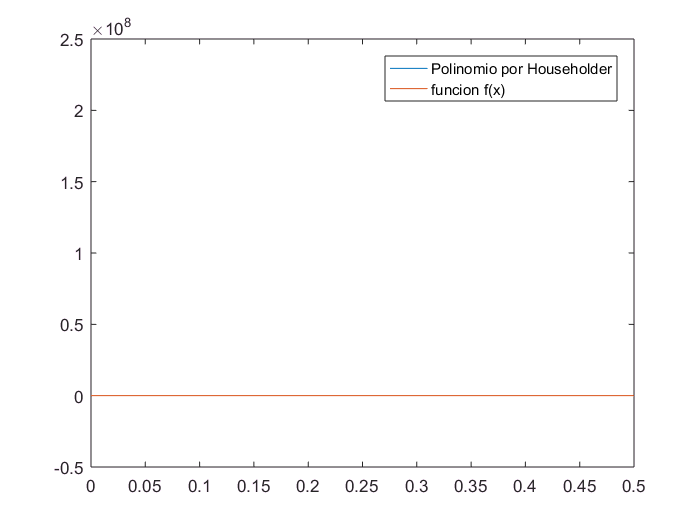

plot(t, pol)
hold on;
fplot(f, [0, 1])
legend('Polinomio por Householder', 'funcion f(x)');
xlim([0 0.5])
hold off;

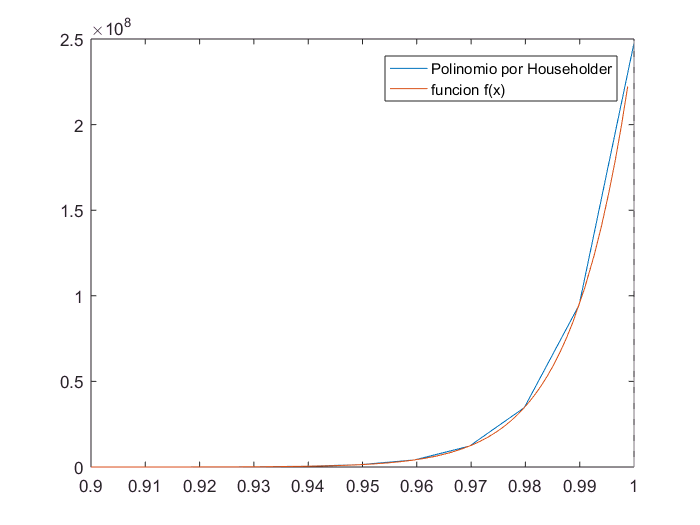

plot(t, pol)
hold on;
fplot(f, [0, 1])
legend('Polinomio por Householder', 'funcion f(x)');
xlim([0.9 1])
hold off;

 Esto se debe al gran crecimiento que presenta la función $f(x)$.

- SVD

A = vander(t);
[U,S,V] = svd(A);
bprima = U'*b;
w = S\bprima;

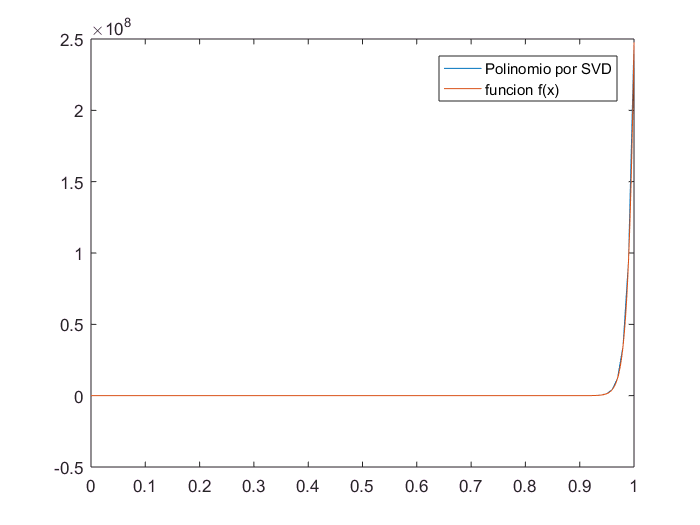

coef = V*w;
coef_15_SVD = coef(1);
pol = polyval(coef, t);
plot(t, pol)
hold on;
fplot(f, [0, 1])
legend('Polinomio por SVD', 'funcion f(x)');
hold off;

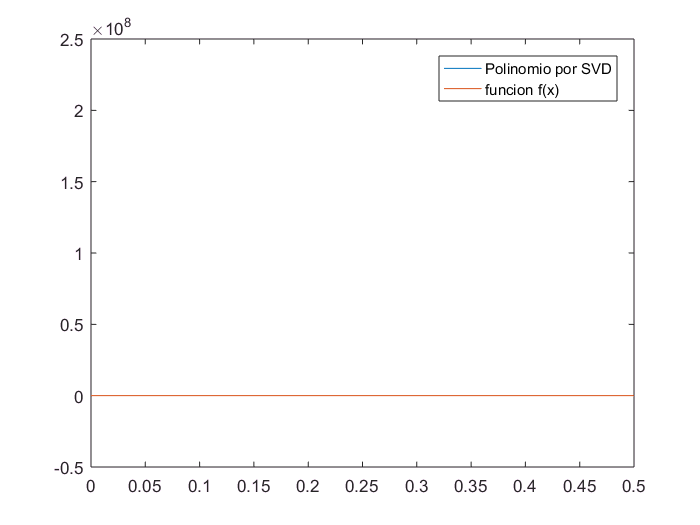

plot(t, pol)
hold on;
fplot(f, [0, 1])
legend('Polinomio por SVD', 'funcion f(x)');
xlim([0 0.5])
hold off;

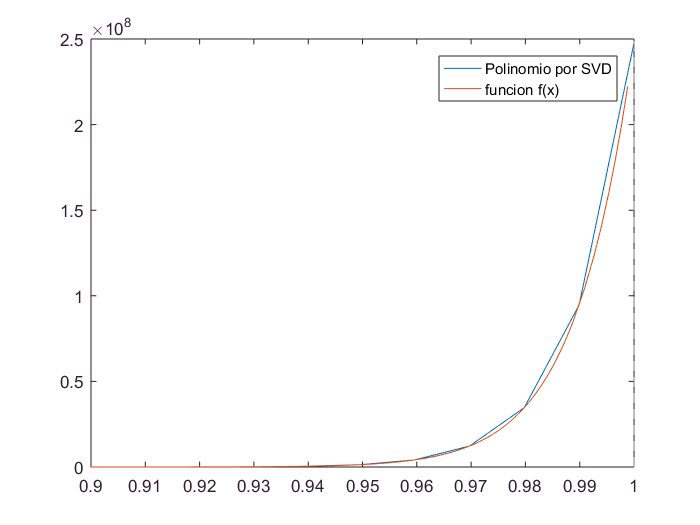

plot(t, pol)
hold on;
fplot(f, [0, 1])
legend('Polinomio por SVD', 'funcion f(x)');
xlim([0.9 1])
hold off;

El comportamiento presente al utilizar descomposición SVD es similiar al por Householder.

Luego, se comparan los coeficientes 15 obtenidos.

coef_15_Householder

coef_15_Householder = 1.1592e+18

coef_15_SVD

coef_15_SVD = -4.8725e+12

Como se puede ver, los coeficientes 15 son considerablemente distintos, esto es debido a que la matriz de Vandermonde es mal condicionada, provocando inestabilidad en los métodos.